Task 1

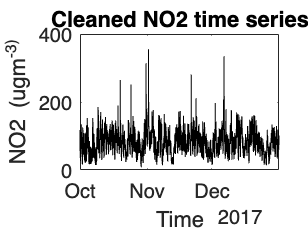


clear
clc
close all

% IMPORT DATA

Data = "AQM_Central_House_Outdoor_Indoor_Q42017_141019 (1).xlsx";         
resolution_min= 15;      % resolution of 15 mins         
N_F = 30;                % number of fourier terms

% minutes in a week
T_week = 7*24*60;            




% CLEAN DATA
opts = detectImportOptions(Data, "Sheet", "AQM_CH_Q42017");

% making sure the right NO2 table values are used
opts.SelectedVariableNames = intersect(string(opts.VariableNames), ["date","time","NO2","NO2u"], "stable");
T = readtable(Data, opts);

% combines the data and time collums so it can be used easily
t = combine_date_time(T.date, T.time);

% cleaning data and removing NaNs, where b is NO2 and t is time
b = T.("NO2");                         
dataclean = ~isnat(t) & ~isnan(b);    
t = t(dataclean);
b = b(dataclean);





% PLOT CLEANED DATA
          
% overall pattern
ff1 = figure;
plot(t, b, "k-")
xlabel("Time");
ylabel("NO2 (ugm^-3)");
title("Cleaned NO2 time series");
xlim([t(1) t(end)]);
saveas(ff1,'1Cleaned NO2 time series','png')





% PLOT AND CALCULATE WEEKLY PATTERNS

% t_week in minutes, bin index for each of the 15 minute bins, 
% and the bin center times
[t_week, idx15, x_week_all] = min_week_bins(t, resolution_min);

m = numel(x_week_all);                  % no. of bins

% mean, variance and number of values for each bin
[mu_week, var_week, n_week] = binned_stats(idx15, b, m);

% removing bins that dont exist
have = n_week > 0 & isfinite(mu_week);
x_week = x_week_all(have);
b_bar = mu_week(have);
s2 = var_week(have);
n_i= n_week(have);

ff2=figure;
plot(x_week, b_bar, "k.-");
xlabel("Minutes of the week");
ylabel("Mean NO2 (ugm^-3)");
title("Average weekly pattern (NO2)");
xlim([x_week(1) x_week(end)]); 
saveas(ff2,'2Average weekly pattern (NO2)','png')




% FOURIER SERIES - FIT AND PLOT

% Fourier model matrix 
A = fourier_matrix(x_week, T_week, N_F);

% weights:
% n_i = number of values in each bin, s2 = variance in each bin
w =n_i./s2

w =     0.0231
    0.0170
    0.0276
    0.0264
    0.0239
    0.0348
    0.0439
    0.0092
    0.0072
    0.0379


gw = isfinite(w) & w > 0;
w(~gw)= min(w(gw))* 1e-6;   


% solving fourier coefficients by weighted least squares 
[x1, b_fit] = wls_solve(A, b_bar, w);

% coefficients
c0 = x1(1)             

c0 = 79.0262

a0 = 2*c0

a0 = 158.0523

an = x1(2:1+N_F)

an =    -5.8514
   -4.5607
   -1.6832
    2.5539
    1.8132
    0.1966
  -10.7865
   -0.2761
   -1.4414
   -0.3487


bn = x1(2+N_F:end)

bn =     6.2537
    2.5564
    3.3305
    1.3105
    0.6288
    5.4306
  -12.5790
   -4.7402
    0.0435
   -1.4511


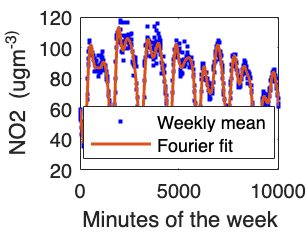


ff3=figure;
plot(x_week, b_bar, ".b", "DisplayName","Weekly mean");
hold on
plot(x_week, b_fit, "-", "LineWidth", 1.5, "DisplayName","Fourier fit");
xlabel("Minutes of the week");
ylabel("NO2 (ugm^-3)");
% title("Comparison of the mean weekly pattern and the Fourier approximation");
legend("Location","best");
xlim([x_week(1) x_week(end)]);
saveas(ff3,'3Comparison of the mean weekly pattern and the Fourier approximation','png')





% CALCULATE AND PLOT STATISTICS

% residuals
v =b_fit-b_bar;

% weighted residual mean and standard diviation
mean_v= mean(v)         

mean_v = -0.4947

std_v = std(v)

std_v = 4.0085


m2=size(A,1);
n2=size(A,2);
DOF=m2-n2;

% weighted unit variance
unit_var=(v'.* w')*v/DOF

unit_var = 0.3837


% covariance matrix and 1-sigma values
AtWA= A'*(A.* w);
covar_mtrx=unit_var*inv(AtWA)

covar_mtrx =     0.0278   -0.0062    0.0029    0.0073   -0.0051    0.0012    0.0031   -0.0099    0.0023   -0.0023   -0.0031    0.0004   -0.0035    0.0008    0.0047    0.0005    0.0009    0.0005    0.0014    0.0007    0.0002    0.0006   -0.0005    0.0004   -0.0004   -0.0011    0.0002    0.0002   -0.0001    0.0009    0.0002    0.0059   -0.0022   -0.0000    0.0044   -0.0038    0.0087   -0.0067   -0.0029    0.0029    0.0003   -0.0000    0.0010   -0.0011   -0.0040   -0.0007   -0.0005   -0.0023   -0.0011    0.0027
   -0.0062    0.0585    0.0011   -0.0021    0.0085   -0.0019   -0.0087    0.0054   -0.0121   -0.0008   -0.0019   -0.0066    0.0012    0.0011    0.0012    0.0056    0.0008    0.0022    0.0013    0.0016    0.0014   -0.0002    0.0009   -0.0008   -0.0008   -0.0003   -0.0008    0.0000    0.0010    0.0003   -0.0000   -0.0023    0.0059    0.0021   -0.0038    0.0131   -0.0105    0.0058   -0.0038   -0.0026    0.0028    0.0013   -0.0011   -0.0031   -0.0019   -0.0046   -0.0030   -0.0016    0.

sigma1 = sqrt(diag(covar_mtrx))

sigma1 =     0.1666
    0.2419
    0.2247
    0.2423
    0.2406
    0.2291
    0.2279
    0.2453
    0.2375
    0.2383




sig_a0 = 2*sigma1(1)

sig_a0 = 0.3333





% table of fourier coefficients
coef_nm = ["a0"; "a"+(1:N_F)'; "b"+(1:N_F)'];
coef_val = [a0; an(:); bn(:)];
coef_sig = [sig_a0; sigma1(2:1+N_F); sigma1(2+N_F:end)];
coef_tbl = table(coef_nm, coef_val, coef_sig, 'VariableNames', {'Coeff','Value','Sigma_1sd'})

coef_tbl = 61×3 table
    Coeff      Value      Sigma_1sd
    _____    _________    _________

    "a0"        158.05     0.33329 
    "a1"       -5.8514     0.24185 
    "a2"       -4.5607     0.22469 
    "a3"       -1.6832      0.2423 
    "a4"        2.5539     0.24063 
    "a5"        1.8132     0.22912 
    "a6"       0.19661      0.2279 
    "a7"       -10.786     0.24528 
    "a8"      -0.27609     0.23748 
    "a9"       -1.4414     0.23832 
    "a10"     -0.34867     0.23599 
    "a11"      -2.1201     0.23479 
    "a12"      -1.7627      0.2344 
    "a13"     -0.33192     0.23523 
    "a14"    -0.046469     0.23534 
    "a15"      0.94386     0.23557 


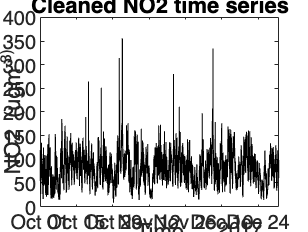



% residuals of the fourier fit 
ff4=figure;
stem(x_week, v, ".k", "MarkerSize", 6);
xlabel("Minutes of the week");
ylabel("Residual (ug/m^-3)");
% title("Residuals of the Fourier fit");
xlim([x_week(1) x_week(end)]);
saveas(ff4,'4Residuals of the Fourier fit','png')

Task 2A

clc
clear

% load and interpret data
data = readtable('barc0130_cwk_building_data.xlsx');


G = data.glass_m2_;
C = data.concrete_m3_;
S = data.steel_tons_;
b = data.cost___;

% coefficient matrix of the three materials
A = [G C S]

A =        22864      142642      104890
       18502      118137       81186
       11022       71376       51301
       15212      104962       75562
       13766       84780       61103
       17290      112704       76553
        3198       20634       15054
       17135      115954       77655
       11432       71939       48936
       21520      150514       97349



% unweighted Least Squares analysis
x1 = (A'*A)\(A'*b)

x1 =    37.8061
   75.1257
  556.4197



% residuals
v =A*x1-b

v = 1.0e+04 *

    3.7822
    3.1228
    1.6276
   -2.0775
   -2.3093
   -2.6150
   -0.6083
    3.0467
   -0.2995
   -3.2949



m = length(b);
n = length(x1);

% unweighted unit variance calculation 
unit_var_1 =(v'*v)/(m-n)

unit_var_1 = 5.1042e+08


% covariance matrix calculation
covariance_mtrx = unit_var_1*inv(A'*A)

covariance_mtrx =    62.8781   -4.9201   -6.7191
   -4.9201    1.2489   -0.7034
   -6.7191   -0.7034    2.4707



% formal 1 sigma uncertainties
sigma1 = sqrt(diag(covariance_mtrx))

sigma1 =     7.9296
    1.1175
    1.5718






% skyscrapers (x-axis)
idx = (1:length(v))'; 

% unweighted residuals
f1 = figure

f1 =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [748 707 560 420]
       Units: 'pixels'

  Show all properties


stem(idx, v,'k','filled')
xlabel('Skyscraper');
ylabel('Residual (£)');
title('Unweighted Residuals');

% unweighted residual mean and standard diviation
mean_v= mean(v)           

mean_v = -43.7152

std_v = std(v)             

std_v = 2.1631e+04

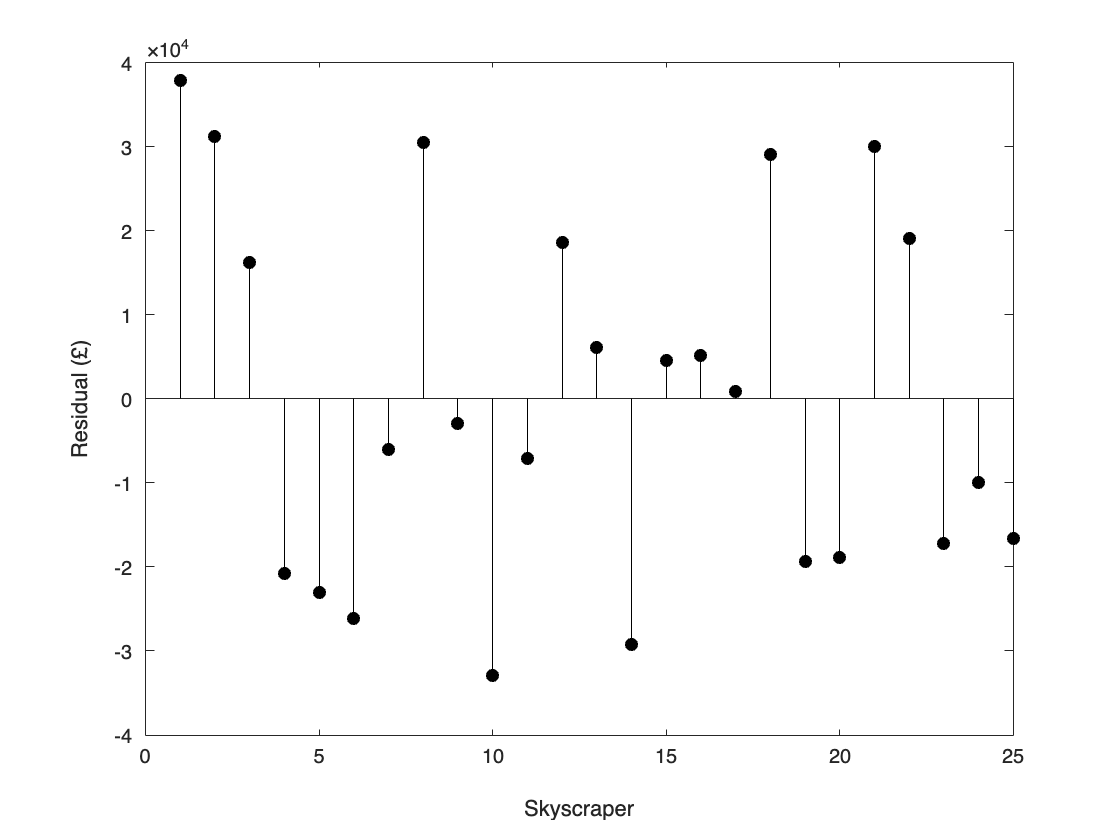


saveas(f1,'Unweighted Residuals','png')

Task 2B

clc
clear


data = readtable('barc0130_cwk_building_data.xlsx');


G = data.glass_m2_;
C = data.concrete_m3_;
S = data.steel_tons_;
b = data.cost___;
w = data.weights;

A = [G C S]

A =        22864      142642      104890
       18502      118137       81186
       11022       71376       51301
       15212      104962       75562
       13766       84780       61103
       17290      112704       76553
        3198       20634       15054
       17135      115954       77655
       11432       71939       48936
       21520      150514       97349



% weights
W = diag(w)

W = 1.0e-05 *

    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0005         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  


% weighted least squares unit cost
x2 = (A'*W*A)\(A'*W*b)

x2 =    43.9687
   74.3534
  556.1765



% residuals
v2 = A*x2-b

v2 = 1.0e+04 *

    4.3048
    3.4263
    1.6598
   -2.6471
   -1.8597
   -2.5262
   -0.5972
    2.7622
   -0.0006
   -4.0252



m = 25;
n = 3;

% weighted unit variance
unitvar_2 =(v2'*W*v2)/(m-n)

unitvar_2 = 0.9340


% weighted covariance matrix
Covar_2 = unitvar_2*inv(A'*W*A)

Covar_2 =     1.6721   -0.3005    0.0605
   -0.3005    0.2222   -0.2566
    0.0605   -0.2566    0.3613



% formal 1 sigma uncertainties
sigma2 = sqrt(diag(Covar_2))

sigma2 =     1.2931
    0.4714
    0.6011







% skyscrapers (x-axis)
idx = (1:length(v2))';   

% weighted residuals 
f2=figure;
stem(idx, v2,'k','filled');
xlabel('Skyscraper');
ylabel('Residual (£)');
title('Weighted Residuals');

% weighted residual mean and standard diviation
mean_v= mean(v2)         

mean_v = 205.7712

std_v2 = std(v2)           

std_v2 = 2.1973e+04

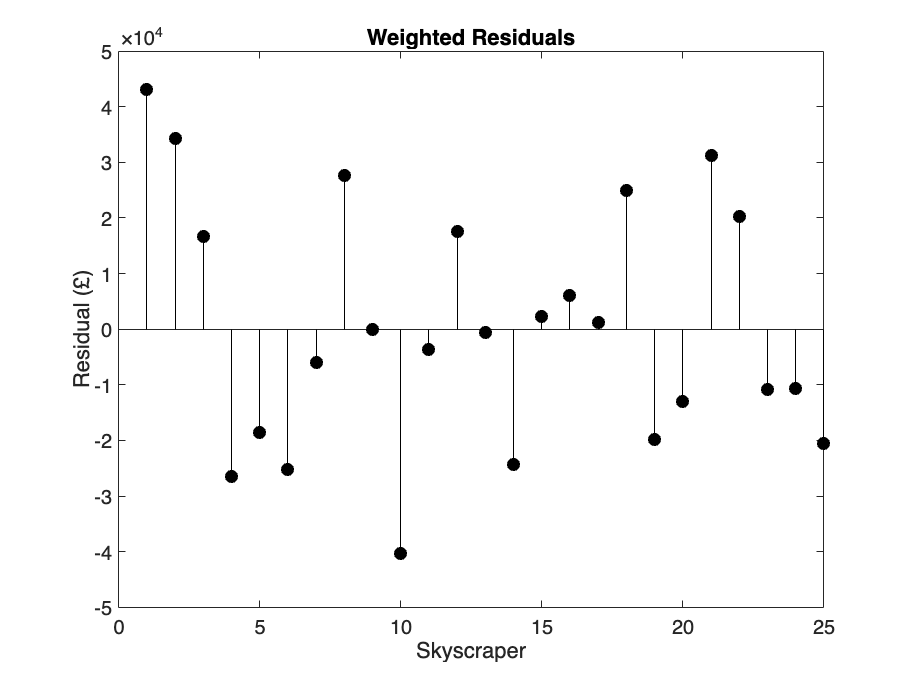


saveas(f2,'Weighted Residuals','png')




% comparison of weighted and unweighted residuals 
f3 = figure;
stem(idx, v,'b', 'filled'); 

Unrecognized function or variable 'v'.

hold on
stem(idx, v2, 'r--');
xlabel('Skyscraper');
ylabel('Residual (£)');
title('Comparison of Unweighted and Weighted Residuals');
legend('Unweighted','Weighted');

saveas(f3,'Comparison of Unweighted and Weighted Residuals','png')



Task 2C


clear
clc

% load data
data = readtable('barc0130_cwk_building_data.xlsx');


G = data.glass_m2_;
C = data.concrete_m3_;
S = data.steel_tons_;
b = data.cost___;
w = data.weights;                 

A = [G C S];
n = size(A,1);
m = size(A,2);

W = diag(w)

W = 1.0e-05 *

    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0005         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  


% weighted least squares from Q2B as required
x2 = (A'*W*A)\(A'*W*b)

x2 =    43.9687
   74.3534
  556.1765



% total cost calculation
A3 = [21800 141230 100000]

A3 =        21800      141230      100000


b3 = A3 * x2

b3 = 6.7077e+07

Task 1 Functions

function dt = combine_date_time(date_col, time_col)
    % combining the date and time data collumns (making sure data is
    % processed correctly using if else statements)
    if isnumeric(date_col)
        d=datetime(date_col,"ConvertFrom","excel");
    else
        d=datetime(date_col);
    end
    d=dateshift(d,"start","day");

    if isduration(time_col)
        t = time_col;
    elseif isnumeric(time_col)
        t = days(time_col);
    else
        t = duration(string(time_col));
    end
    dt=d+t;
end

% processing bin data
function [min_week, bin_idx, t_bin] = min_week_bins(dt, dt_min)
% this code makes the graphs start at monday midnight
    dow = day(dt,"dayofweek");         
    dow_mon0 = mod(dow+ 5, 7);          
    min_week = dow_mon0*1440 + hour(dt)*60 + minute(dt);

    bin0=floor(min_week/dt_min);        
    bin_idx = bin0 + 1;                   

    t_bin = (0:(7*24*60/dt_min-1))'*dt_min;
end

% returning mean, variance, number of points in each bin
function [mu, v, n] = binned_stats(bin_idx, y, m)
    n = accumarray(bin_idx, 1, [m 1], @sum, 0);
    mu = accumarray(bin_idx, y, [m 1], @mean, NaN);
    v = accumarray(bin_idx, y, [m 1], @(x)var(x,1), NaN); 
end

% returning the design matrix A
function A = fourier_matrix(x_min, T, N)
    x_min = x_min(:);
    m = numel(x_min);
    A = ones(m, 2*N + 1);

    angle = 2*pi*x_min/T;
    for k = 1:N
        A(:,1+k)= cos(k*angle);
        A(:,1+N+k)= sin(k*angle);
    end
end

% returnes fitted coefficients vector and fitted curva values
function [x_h, y_h] = wls_solve(A, y, w)
    y = y(:);w=w(:);
    sw = sqrt(w);
    Aw = A.*sw;
    yw = y.*sw;
    x_h = Aw\yw;
    y_h = A*x_h;
end


